syms s u
W=  1+(1+0.65.*s-1.2.*s.^2-0.4.*s.^3+0.35.*s.^4).*cos(u)...
    +(1.4.*s-0.4.*s.^2-1.5.*s.^3-0.35.*s.^4).*sin(u)

$$W = \cos\left(u\right)\,\left(\frac{7\,s^{4}}{20}-\frac{2\,s^{3}}{5}-\frac{6\,s^{2}}{5}+\frac{13\,s}{20}+1\right)-\sin\left(u\right)\,\left(\frac{7\,s^{4}}{20}+\frac{3\,s^{3}}{2}+\frac{2\,s^{2}}{5}-\frac{7\,s}{5}\right)+1$$

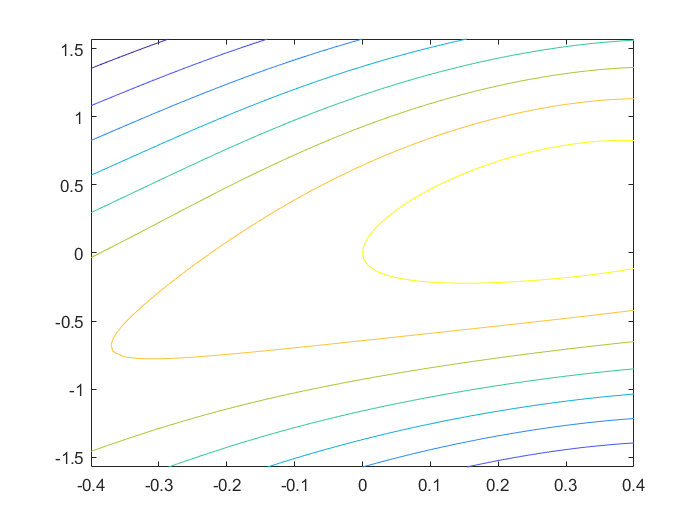

%fsurf(W,[-0.4 0.4 -pi/2 pi/2],'MeshDensity',100)
%hold on
fcontour(W,[-0.4 0.4 -pi/2 pi/2])

sol1=vpasolve(diff(W,s)==0)

sol1 = struct with fields:
    s: [1×1 sym]
    u: [1×1 sym]


sol2=vpasolve(diff(W,u)==0)

sol2 = struct with fields:
    s: [1×1 sym]
    u: [1×1 sym]


x=sol2.s

$$x = 0$$

y=sol1.u

$$y = -0.11850746603039468885438119603971$$

z = subs(W,s,sol2.s)

$$z = \cos\left(u\right)+1$$

z = subs(z,u,sol1.u)

$$z = 1.9929862045048125359667041552017$$

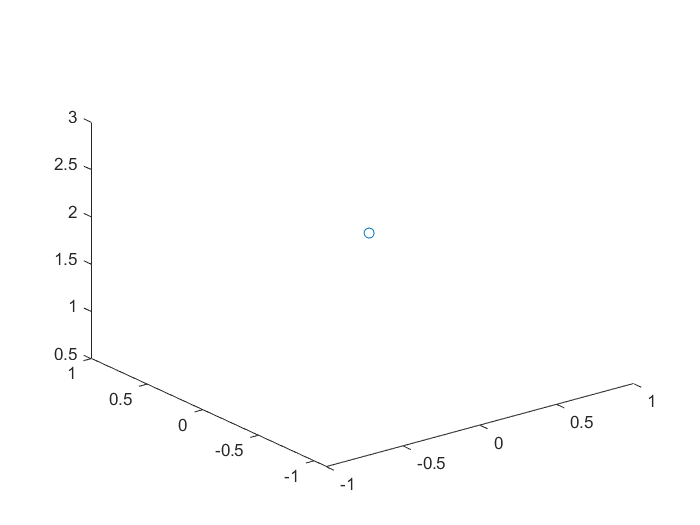

plot3(x,y,z,'o')

x=sol1.s

$$x = 0.2034954575007827470584592949227$$

y=sol2.u

$$y = 0$$

z = subs(W,s,sol1.s)

$$z = 1.0798090219557828978625922043772\,\cos\left(u\right)+0.25508904973300784809808331819573\,\sin\left(u\right)+1$$

z = subs(z,u,sol2.u)

$$z = 2.0798090219557828978625922043772$$

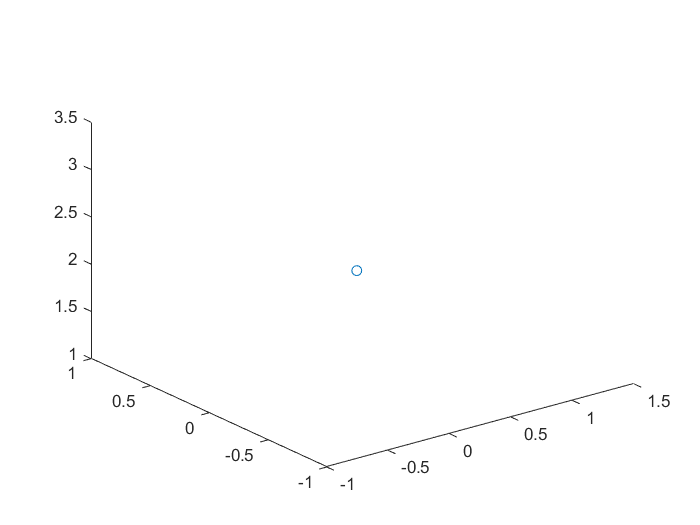

plot3(x,y,z,'o')

cp1 = subs(W,s,sol1.s)

$$cp1 = 1.0798090219557828978625922043772\,\cos\left(u\right)+0.25508904973300784809808331819573\,\sin\left(u\right)+1$$

cp1 = subs(cp1,u,sol2.u)

$$cp1 = 2.0798090219557828978625922043772$$

cp2 = subs(W,s,sol1.u)

$$cp2 = 0.90685208420942361402793356983189\,\cos\left(u\right)-0.16910061056726124089212388062184\,\sin\left(u\right)+1$$

cp2 = subs(cp1,u,sol2.s) 

$$cp2 = 2.0798090219557828978625922043772$$

%hold off

